# Simulación

## Parámetros de entrada


N_bits=1000000%Número de bits

N_bits = 1000000

M=8

M = 8

n=log2(M)

n = 3

N=0

N = 0

## Generador de secuencia

Secuencia=randi([0, 1], 1, N_bits) %Genera una secuencia de N_bits

Secuencia =      1     0     0     0     1     0     1     1     0     1     1     0     1     1     1     0     1     1     1     0     1     1     0     0     0     1     1     1     0     0     1     0     1     1     1     1     0     1     0     1     0     0     0     0     1     0     0     1     0     0


## Modulador-M-ASK

%Se divide la secuencia en n bits
secuencia_n=sep(Secuencia,n);
%secuencia
secuencia_x=reshape(secuencia_n',1,[])';
Numero_bits_transmitidos=length(secuencia_x)

Numero_bits_transmitidos = 1000002

%Se obtiene los valores de la tabla de correspondecia
[gray,bk,fik,ik,qk]=table_cor(n,N)

gray = 8×3 logical array
   0   0   0
   0   0   1
   0   1   1
   0   1   0
   1   1   0
   1   1   1
   1   0   1
   1   0   0


bk =      0     1     2     3     4     5     6     7


fik =          0    0.7854    1.5708    2.3562    3.1416    3.9270    4.7124    5.4978


ik =     1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071


qk =          0    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071


Ik=zeros(1,length(secuencia_n))';
Qk=zeros(1,length(secuencia_n))';
fase_modulado=zeros(1,length(secuencia_n))';

for i=1:M
    indice = find(ismember(secuencia_n, gray(i,:),"rows"));
    %indice es un vector
    indice=indice';
    Ik(indice)=ik(i); 
    Qk(indice)=qk(i);
    fase_modulado(indice)=fik(i);
end

## Canal AWGN

tam=length(secuencia_n);
Ac=3; %amplitud de la portadora

snrDB=0.5:0.1:2.5; % Relacion señal a ruido de 5dB a 25dB
snr=10.^snrDB;
yb=snr;
Data_Ik=[]; % Contiene los valores de Ik +ni
Data_Qk=[]; % Contiene los valores de Qk +nq
Data_Z=[]


Data_Z =

     []



for yb_=snr
    varianza=(Ac^2)/(2*yb_*log2(M));%varianza
    mu=0; %media igual a 0
    desv_estandar=sqrt(varianza);
    %se genera 2 componentes del ruido independientes
    ni = normrnd(mu,desv_estandar,1,tam)';
    nq= normrnd(mu,desv_estandar,1,tam)';
    %ni=rand(1,tam)';
    %nq=rand(1,tam)';
    Data_Ik=[Data_Ik,ni+Ik];
    Data_Qk=[Data_Qk,nq+Qk];
    Data_Z=[Data_Z,sqrt((ni+Ik).^2 +(nq+Qk).^2)];
end


## Demodulador - arctan

[nr,m]=size(snr);
fase_recuperado=[]


fase_recuperado =

     []



parfor i=1:m
    fase_recuperado=[fase_recuperado,atan2_0_to_2pi(Data_Qk(:,i),Data_Ik(:,i))];%Es la fase resultante afectada por el ruido
end

## Demodulador - Etapa del cuantizador

%cuantizador
umbrales_QPSK=umbQ(fik);
fase_cuantizado=[];

for i=1:length(snr)
    fase=fase_recuperado(:,i);
    %disp(fase);
    %disp("_______________");
    for j=1:length(fase)
       
        if fase(j)<=umbrales_QPSK(1) || fase(j)>umbrales_QPSK(end)
            fase(j)=fik(1);
            
        elseif fase(j)> umbrales_QPSK(1) && fase(j)<=umbrales_QPSK(2)
            fase(j)=fik(2);

            
        end

    end
    fase_cuantizado=[fase_cuantizado, fase];

end



## Demodulador - Convertidor de datos

[rx,ry]=size(fase_cuantizado);
contenedor=[];
secuencia_y=zeros(rx,n);
for q=1:m 
    for i=1:M
        indice = find(ismember(fase_cuantizado(:,q), fik(i),"rows"));
        %for j=indice'
        %    secuencia_y(j, :)=gray(i,:);
        %end
        indice=indice';
        v=gray(i,:);
        secuencia_y(indice, :) = repmat(v, length(indice), 1);

    end
    contenedor=[contenedor,reshape(secuencia_y',1,[])'];
end



## Pb

Mpsk=M; 
Lpsk=log2(Mpsk);
xpsk=sqrt(2*Lpsk*snr*sin(pi/Mpsk)^2);
pbPSK=(2/Lpsk)*Q(xpsk);


## BER

BER=[]


BER =

     []



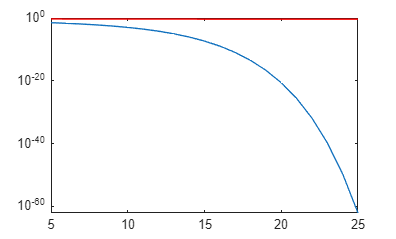

parfor i=1:m
    error=find(secuencia_x~=contenedor(:,i));
    ber=length(error)/Numero_bits_transmitidos;
    BER=[BER,ber];
end
num_bins_x = 50;  % Ajusta el número de bins en X
num_bins_y = 50;  % Ajusta el número de bins en Y
num_bins_z = 50;  % Ajusta el número de bins en Z
semilogy(snrDB*10, pbPSK); 
hold on 
semilogy(snrDB*10,BER,'r')

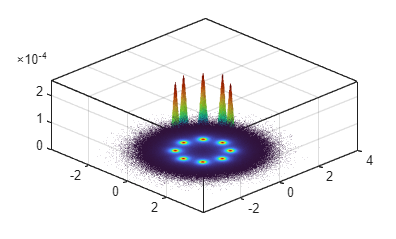

figure
a=colormap("turbo");

qk1=Data_Qk(:,end);
ik1=Data_Ik(:,end);
hold off
histogram2(Data_Qk,Data_Ik,'Normalization', 'probability','faceColor','flat', 'NumBins', [500,500])

%histogram2(qk1,ik1,'Normalization', 'probability','faceColor','flat', 'NumBins', [500,500])

%r=histogram2(Data_Qk,Data_Ik)




